%Flight Conditions
V = 350 %kts 

V = 350

h = 25000 %ft

h = 25000

DynVisc = 3.2166*10^(-7); %Slug/ft-s CHANGES WITH ALT
W = 121893*0.946

W = 1.1531e+05


[TempRat, PresRat, DensRat, SpeedSound] = ISA(h);
V=V*1.688

V = 590.8000

M = V/SpeedSound

M = 0.5817


%Airfoil Parameters
Cla = 2*pi

Cla = 6.2832

Tmax = 0.15

Tmax = 0.1500

LocMaxT = 0.4

LocMaxT = 0.4000

PerLamFlow = 0.1

PerLamFlow = 0.1000

CLDMin = 0.1

CLDMin = 0.1000


%Planform Parameters
S = 1303; %ft^2
AR = 10.68

AR = 10.6800

AR2 = 5.23

AR2 = 5.2300

b2=100

b2 = 100

TaperRatio = 0.6;
b = sqrt(AR*S)

b = 117.9663

Q = 1.01

Q = 1.0100

SweepQuartC = 0;
e = 0.9;
K = 1/(e*pi*AR)

K = 0.0331


%Fuselage Parameters
Df = 18; %ft
LNose = 16; %ft
LMid = 44; %ft
LTail = 40.3 %ft

LTail = 40.3000

DBase = 4 %ft

DBase = 4

ABase = pi*DBase^2/4

ABase = 12.5664

UpsweepAngle = atan((Df/2-DBase/2)/LTail); %rad

%Vertical Tail Parameters NOTE: Half Wing
Sv = 300*2; %ft^2
ARv = 7.05;
TaperRatiov = 0.55;
bv = sqrt(ARv*Sv);
QVt = 1.05;
LocMaxTv = 0.35;
Tmaxv = 0.12

Tmaxv = 0.1200


%Horizontal Tail Parameters
Sh = 400; %ft^2
ARh = 6.42;
TaperRatioh = 0.35;
bh = sqrt(ARh*Sh);
QHt = 1.05;
LocMaxTh = 0.35;
Tmaxh = 0.12

Tmaxh = 0.1200


%Nacelle Parameters
LNacelle = 78/12;
DNacelle = 34/12;

[CDoWing] = WingZeroLiftDrag(V,Q,TaperRatio,DynVisc,0,S,AR,b,h,LocMaxT,Df,PerLamFlow,Tmax);

V = 997.2704

M = 0.9820

Cr = 13.8069

Cmac = 11.2756

Ymac = 27.0339

SweepMaxT = -0.8047

Cf = 12.9642

Sexp = 1.0621e+03

Re = 6.2785e+07

SweepMaxT = -0.8047

FF = 1.7037

Swet = 2.1825e+03

CDo = 0.0064


[CDoHt] = WingZeroLiftDrag(V,QHt,TaperRatioh,DynVisc,0,Sh,ARh,bh,h,LocMaxTh,0,PerLamFlow,Tmaxh);

V = 997.2704

M = 0.9820

Cr = 11.6939

Cmac = 8.5033

Ymac = 10.6356

SweepMaxT = -1.7183

Cf = 11.6939

Sexp = 400

Re = 4.7348e+07

SweepMaxT = -1.7183

FF = 1.6379

Swet = 815.7600

CDo = 0.0082


CDoHt = CDoHt*Sh/S

CDoHt = 0.0025


[CDoVt] = WingZeroLiftDrag(V,QVt,TaperRatiov,DynVisc,0,Sv,ARv,bv,h,LocMaxTv,0,PerLamFlow,Tmaxv);

V = 997.2704

M = 0.9820

Cr = 11.9036

Cmac = 9.4845

Ymac = 14.6861

SweepMaxT = -0.9437

Cf = 11.9036

Sexp = 600

Re = 5.2812e+07

SweepMaxT = -0.9437

FF = 1.6380

Swet = 1.2236e+03

CDo = 0.0080


CDoVt = CDoVt*Sv/S/2

CDoVt = 0.0019


[CDoFuse] = ParaDragFuse(h,V,LMid,LNose,LTail,Df,DynVisc,S)

FF = 1.3607

CDoFuse = 0.0090


[CDoNacelle] = 8*ParaDragNacelle(h,V,LNacelle,DNacelle,DynVisc,S)

CDoNacelle = 0.0013


UpSweepDrag = 3.83*UpsweepAngle^2.5*pi*Df^2/4/S

UpSweepDrag = 0.0092


CDoCamber = e/(1-e)*K*CLDMin^2

CDoCamber = 0.0030


BaseDrag = (0.1+0.1222*M^8)*ABase/S

BaseDrag = 9.7988e-04


CDoTotal = CDoWing + CDoHt + CDoVt + CDoFuse + UpSweepDrag + BaseDrag + CDoNacelle + CDoCamber

CDoTotal = 0.0343


%Induced Drag Factor

% Ne = 4; %Num of engines ON TOP of Wing
% TaperFunc = 0.005*(1+1.5*(TaperRatio-0.6)^2)
% K = (1+(0.142+TaperFunc*AR*(10*Tmax)^(0.33))/(cosd(SweepQuartC)^2)+(0.1*(3*Ne+1))/((4+AR)^0.8))*(1+0.12*M^6)/(pi*AR)
% e = 1/(K*AR*pi)

CL = -0.5:0.01:1.5

CL =    -0.5000   -0.4900   -0.4800   -0.4700   -0.4600   -0.4500   -0.4400   -0.4300   -0.4200   -0.4100   -0.4000   -0.3900   -0.3800   -0.3700   -0.3600   -0.3500   -0.3400   -0.3300   -0.3200   -0.3100   -0.3000   -0.2900   -0.2800   -0.2700   -0.2600   -0.2500   -0.2400   -0.2300   -0.2200   -0.2100   -0.2000   -0.1900   -0.1800   -0.1700   -0.1600   -0.1500   -0.1400   -0.1300   -0.1200   -0.1100   -0.1000   -0.0900   -0.0800   -0.0700   -0.0600   -0.0500   -0.0400   -0.0300   -0.0200   -0.0100



LDMax = 0;

for x=1:201
    
   CD(x) = CDoTotal + K*CL(x)^2
   
   if CL(x)/CD(x)>LDMax
       
       LDMax = CL(x)/CD(x)
       
   end
   
end

CD =     0.0425    0.0459    0.0456    0.0453    0.0450    0.0447    0.0444    0.0441    0.0438    0.0435    0.0433    0.0430    0.0427    0.0425    0.0422    0.0420    0.0418    0.0416    0.0413    0.0411    0.0409    0.0407    0.0406    0.0404    0.0402    0.0400    0.0399    0.0397    0.0396    0.0394    0.0393    0.0392    0.0390    0.0389    0.0388    0.0387    0.0386    0.0385    0.0384    0.0384    0.0383    0.0382    0.0382    0.0381    0.0381    0.0380    0.0380    0.0380    0.0380    0.0380


CD =     0.0425    0.0422    0.0456    0.0453    0.0450    0.0447    0.0444    0.0441    0.0438    0.0435    0.0433    0.0430    0.0427    0.0425    0.0422    0.0420    0.0418    0.0416    0.0413    0.0411    0.0409    0.0407    0.0406    0.0404    0.0402    0.0400    0.0399    0.0397    0.0396    0.0394    0.0393    0.0392    0.0390    0.0389    0.0388    0.0387    0.0386    0.0385    0.0384    0.0384    0.0383    0.0382    0.0382    0.0381    0.0381    0.0380    0.0380    0.0380    0.0380    0.0380


CD =     0.0425    0.0422    0.0419    0.0453    0.0450    0.0447    0.0444    0.0441    0.0438    0.0435    0.0433    0.0430    0.0427    0.0425    0.0422    0.0420    0.0418    0.0416    0.0413    0.0411    0.0409    0.0407    0.0406    0.0404    0.0402    0.0400    0.0399    0.0397    0.0396    0.0394    0.0393    0.0392    0.0390    0.0389    0.0388    0.0387    0.0386    0.0385    0.0384    0.0384    0.0383    0.0382    0.0382    0.0381    0.0381    0.0380    0.0380    0.0380    0.0380    0.0380


CD =     0.0425    0.0422    0.0419    0.0416    0.0450    0.0447    0.0444    0.0441    0.0438    0.0435    0.0433    0.0430    0.0427    0.0425    0.0422    0.0420    0.0418    0.0416    0.0413    0.0411    0.0409    0.0407    0.0406    0.0404    0.0402    0.0400    0.0399    0.0397    0.0396    0.0394    0.0393    0.0392    0.0390    0.0389    0.0388    0.0387    0.0386    0.0385    0.0384    0.0384    0.0383    0.0382    0.0382    0.0381    0.0381    0.0380    0.0380    0.0380    0.0380    0.0380


CD =     0.0425    0.0422    0.0419    0.0416    0.0413    0.0447    0.0444    0.0441    0.0438    0.0435    0.0433    0.0430    0.0427    0.0425    0.0422    0.0420    0.0418    0.0416    0.0413    0.0411    0.0409    0.0407    0.0406    0.0404    0.0402    0.0400    0.0399    0.0397    0.0396    0.0394    0.0393    0.0392    0.0390    0.0389    0.0388    0.0387    0.0386    0.0385    0.0384    0.0384    0.0383    0.0382    0.0382    0.0381    0.0381    0.0380    0.0380    0.0380    0.0380    0.0380


CD =     0.0425    0.0422    0.0419    0.0416    0.0413    0.0410    0.0444    0.0441    0.0438    0.0435    0.0433    0.0430    0.0427    0.0425    0.0422    0.0420    0.0418    0.0416    0.0413    0.0411    0.0409    0.0407    0.0406    0.0404    0.0402    0.0400    0.0399    0.0397    0.0396    0.0394    0.0393    0.0392    0.0390    0.0389    0.0388    0.0387    0.0386    0.0385    0.0384    0.0384    0.0383    0.0382    0.0382    0.0381    0.0381    0.0380    0.0380    0.0380    0.0380    0.0380


CD =     0.0425    0.0422    0.0419    0.0416    0.0413    0.0410    0.0407    0.0441    0.0438    0.0435    0.0433    0.0430    0.0427    0.0425    0.0422    0.0420    0.0418    0.0416    0.0413    0.0411    0.0409    0.0407    0.0406    0.0404    0.0402    0.0400    0.0399    0.0397    0.0396    0.0394    0.0393    0.0392    0.0390    0.0389    0.0388    0.0387    0.0386    0.0385    0.0384    0.0384    0.0383    0.0382    0.0382    0.0381    0.0381    0.0380    0.0380    0.0380    0.0380    0.0380


CD =     0.0425    0.0422    0.0419    0.0416    0.0413    0.0410    0.0407    0.0404    0.0438    0.0435    0.0433    0.0430    0.0427    0.0425    0.0422    0.0420    0.0418    0.0416    0.0413    0.0411    0.0409    0.0407    0.0406    0.0404    0.0402    0.0400    0.0399    0.0397    0.0396    0.0394    0.0393    0.0392    0.0390    0.0389    0.0388    0.0387    0.0386    0.0385    0.0384    0.0384    0.0383    0.0382    0.0382    0.0381    0.0381    0.0380    0.0380    0.0380    0.0380    0.0380


CD =     0.0425    0.0422    0.0419    0.0416    0.0413    0.0410    0.0407    0.0404    0.0401    0.0435    0.0433    0.0430    0.0427    0.0425    0.0422    0.0420    0.0418    0.0416    0.0413    0.0411    0.0409    0.0407    0.0406    0.0404    0.0402    0.0400    0.0399    0.0397    0.0396    0.0394    0.0393    0.0392    0.0390    0.0389    0.0388    0.0387    0.0386    0.0385    0.0384    0.0384    0.0383    0.0382    0.0382    0.0381    0.0381    0.0380    0.0380    0.0380    0.0380    0.0380


CD =     0.0425    0.0422    0.0419    0.0416    0.0413    0.0410    0.0407    0.0404    0.0401    0.0398    0.0433    0.0430    0.0427    0.0425    0.0422    0.0420    0.0418    0.0416    0.0413    0.0411    0.0409    0.0407    0.0406    0.0404    0.0402    0.0400    0.0399    0.0397    0.0396    0.0394    0.0393    0.0392    0.0390    0.0389    0.0388    0.0387    0.0386    0.0385    0.0384    0.0384    0.0383    0.0382    0.0382    0.0381    0.0381    0.0380    0.0380    0.0380    0.0380    0.0380


CD =     0.0425    0.0422    0.0419    0.0416    0.0413    0.0410    0.0407    0.0404    0.0401    0.0398    0.0396    0.0430    0.0427    0.0425    0.0422    0.0420    0.0418    0.0416    0.0413    0.0411    0.0409    0.0407    0.0406    0.0404    0.0402    0.0400    0.0399    0.0397    0.0396    0.0394    0.0393    0.0392    0.0390    0.0389    0.0388    0.0387    0.0386    0.0385    0.0384    0.0384    0.0383    0.0382    0.0382    0.0381    0.0381    0.0380    0.0380    0.0380    0.0380    0.0380


CD =     0.0425    0.0422    0.0419    0.0416    0.0413    0.0410    0.0407    0.0404    0.0401    0.0398    0.0396    0.0393    0.0427    0.0425    0.0422    0.0420    0.0418    0.0416    0.0413    0.0411    0.0409    0.0407    0.0406    0.0404    0.0402    0.0400    0.0399    0.0397    0.0396    0.0394    0.0393    0.0392    0.0390    0.0389    0.0388    0.0387    0.0386    0.0385    0.0384    0.0384    0.0383    0.0382    0.0382    0.0381    0.0381    0.0380    0.0380    0.0380    0.0380    0.0380


CD =     0.0425    0.0422    0.0419    0.0416    0.0413    0.0410    0.0407    0.0404    0.0401    0.0398    0.0396    0.0393    0.0391    0.0425    0.0422    0.0420    0.0418    0.0416    0.0413    0.0411    0.0409    0.0407    0.0406    0.0404    0.0402    0.0400    0.0399    0.0397    0.0396    0.0394    0.0393    0.0392    0.0390    0.0389    0.0388    0.0387    0.0386    0.0385    0.0384    0.0384    0.0383    0.0382    0.0382    0.0381    0.0381    0.0380    0.0380    0.0380    0.0380    0.0380


CD =     0.0425    0.0422    0.0419    0.0416    0.0413    0.0410    0.0407    0.0404    0.0401    0.0398    0.0396    0.0393    0.0391    0.0388    0.0422    0.0420    0.0418    0.0416    0.0413    0.0411    0.0409    0.0407    0.0406    0.0404    0.0402    0.0400    0.0399    0.0397    0.0396    0.0394    0.0393    0.0392    0.0390    0.0389    0.0388    0.0387    0.0386    0.0385    0.0384    0.0384    0.0383    0.0382    0.0382    0.0381    0.0381    0.0380    0.0380    0.0380    0.0380    0.0380


CD =     0.0425    0.0422    0.0419    0.0416    0.0413    0.0410    0.0407    0.0404    0.0401    0.0398    0.0396    0.0393    0.0391    0.0388    0.0386    0.0420    0.0418    0.0416    0.0413    0.0411    0.0409    0.0407    0.0406    0.0404    0.0402    0.0400    0.0399    0.0397    0.0396    0.0394    0.0393    0.0392    0.0390    0.0389    0.0388    0.0387    0.0386    0.0385    0.0384    0.0384    0.0383    0.0382    0.0382    0.0381    0.0381    0.0380    0.0380    0.0380    0.0380    0.0380


CD =     0.0425    0.0422    0.0419    0.0416    0.0413    0.0410    0.0407    0.0404    0.0401    0.0398    0.0396    0.0393    0.0391    0.0388    0.0386    0.0383    0.0418    0.0416    0.0413    0.0411    0.0409    0.0407    0.0406    0.0404    0.0402    0.0400    0.0399    0.0397    0.0396    0.0394    0.0393    0.0392    0.0390    0.0389    0.0388    0.0387    0.0386    0.0385    0.0384    0.0384    0.0383    0.0382    0.0382    0.0381    0.0381    0.0380    0.0380    0.0380    0.0380    0.0380


CD =     0.0425    0.0422    0.0419    0.0416    0.0413    0.0410    0.0407    0.0404    0.0401    0.0398    0.0396    0.0393    0.0391    0.0388    0.0386    0.0383    0.0381    0.0416    0.0413    0.0411    0.0409    0.0407    0.0406    0.0404    0.0402    0.0400    0.0399    0.0397    0.0396    0.0394    0.0393    0.0392    0.0390    0.0389    0.0388    0.0387    0.0386    0.0385    0.0384    0.0384    0.0383    0.0382    0.0382    0.0381    0.0381    0.0380    0.0380    0.0380    0.0380    0.0380


CD =     0.0425    0.0422    0.0419    0.0416    0.0413    0.0410    0.0407    0.0404    0.0401    0.0398    0.0396    0.0393    0.0391    0.0388    0.0386    0.0383    0.0381    0.0379    0.0413    0.0411    0.0409    0.0407    0.0406    0.0404    0.0402    0.0400    0.0399    0.0397    0.0396    0.0394    0.0393    0.0392    0.0390    0.0389    0.0388    0.0387    0.0386    0.0385    0.0384    0.0384    0.0383    0.0382    0.0382    0.0381    0.0381    0.0380    0.0380    0.0380    0.0380    0.0380


CD =     0.0425    0.0422    0.0419    0.0416    0.0413    0.0410    0.0407    0.0404    0.0401    0.0398    0.0396    0.0393    0.0391    0.0388    0.0386    0.0383    0.0381    0.0379    0.0377    0.0411    0.0409    0.0407    0.0406    0.0404    0.0402    0.0400    0.0399    0.0397    0.0396    0.0394    0.0393    0.0392    0.0390    0.0389    0.0388    0.0387    0.0386    0.0385    0.0384    0.0384    0.0383    0.0382    0.0382    0.0381    0.0381    0.0380    0.0380    0.0380    0.0380    0.0380


CD =     0.0425    0.0422    0.0419    0.0416    0.0413    0.0410    0.0407    0.0404    0.0401    0.0398    0.0396    0.0393    0.0391    0.0388    0.0386    0.0383    0.0381    0.0379    0.0377    0.0375    0.0409    0.0407    0.0406    0.0404    0.0402    0.0400    0.0399    0.0397    0.0396    0.0394    0.0393    0.0392    0.0390    0.0389    0.0388    0.0387    0.0386    0.0385    0.0384    0.0384    0.0383    0.0382    0.0382    0.0381    0.0381    0.0380    0.0380    0.0380    0.0380    0.0380


CD =     0.0425    0.0422    0.0419    0.0416    0.0413    0.0410    0.0407    0.0404    0.0401    0.0398    0.0396    0.0393    0.0391    0.0388    0.0386    0.0383    0.0381    0.0379    0.0377    0.0375    0.0372    0.0407    0.0406    0.0404    0.0402    0.0400    0.0399    0.0397    0.0396    0.0394    0.0393    0.0392    0.0390    0.0389    0.0388    0.0387    0.0386    0.0385    0.0384    0.0384    0.0383    0.0382    0.0382    0.0381    0.0381    0.0380    0.0380    0.0380    0.0380    0.0380


CD =     0.0425    0.0422    0.0419    0.0416    0.0413    0.0410    0.0407    0.0404    0.0401    0.0398    0.0396    0.0393    0.0391    0.0388    0.0386    0.0383    0.0381    0.0379    0.0377    0.0375    0.0372    0.0371    0.0406    0.0404    0.0402    0.0400    0.0399    0.0397    0.0396    0.0394    0.0393    0.0392    0.0390    0.0389    0.0388    0.0387    0.0386    0.0385    0.0384    0.0384    0.0383    0.0382    0.0382    0.0381    0.0381    0.0380    0.0380    0.0380    0.0380    0.0380


CD =     0.0425    0.0422    0.0419    0.0416    0.0413    0.0410    0.0407    0.0404    0.0401    0.0398    0.0396    0.0393    0.0391    0.0388    0.0386    0.0383    0.0381    0.0379    0.0377    0.0375    0.0372    0.0371    0.0369    0.0404    0.0402    0.0400    0.0399    0.0397    0.0396    0.0394    0.0393    0.0392    0.0390    0.0389    0.0388    0.0387    0.0386    0.0385    0.0384    0.0384    0.0383    0.0382    0.0382    0.0381    0.0381    0.0380    0.0380    0.0380    0.0380    0.0380


CD =     0.0425    0.0422    0.0419    0.0416    0.0413    0.0410    0.0407    0.0404    0.0401    0.0398    0.0396    0.0393    0.0391    0.0388    0.0386    0.0383    0.0381    0.0379    0.0377    0.0375    0.0372    0.0371    0.0369    0.0367    0.0402    0.0400    0.0399    0.0397    0.0396    0.0394    0.0393    0.0392    0.0390    0.0389    0.0388    0.0387    0.0386    0.0385    0.0384    0.0384    0.0383    0.0382    0.0382    0.0381    0.0381    0.0380    0.0380    0.0380    0.0380    0.0380


CD =     0.0425    0.0422    0.0419    0.0416    0.0413    0.0410    0.0407    0.0404    0.0401    0.0398    0.0396    0.0393    0.0391    0.0388    0.0386    0.0383    0.0381    0.0379    0.0377    0.0375    0.0372    0.0371    0.0369    0.0367    0.0365    0.0400    0.0399    0.0397    0.0396    0.0394    0.0393    0.0392    0.0390    0.0389    0.0388    0.0387    0.0386    0.0385    0.0384    0.0384    0.0383    0.0382    0.0382    0.0381    0.0381    0.0380    0.0380    0.0380    0.0380    0.0380


CD =     0.0425    0.0422    0.0419    0.0416    0.0413    0.0410    0.0407    0.0404    0.0401    0.0398    0.0396    0.0393    0.0391    0.0388    0.0386    0.0383    0.0381    0.0379    0.0377    0.0375    0.0372    0.0371    0.0369    0.0367    0.0365    0.0363    0.0399    0.0397    0.0396    0.0394    0.0393    0.0392    0.0390    0.0389    0.0388    0.0387    0.0386    0.0385    0.0384    0.0384    0.0383    0.0382    0.0382    0.0381    0.0381    0.0380    0.0380    0.0380    0.0380    0.0380


CD =     0.0425    0.0422    0.0419    0.0416    0.0413    0.0410    0.0407    0.0404    0.0401    0.0398    0.0396    0.0393    0.0391    0.0388    0.0386    0.0383    0.0381    0.0379    0.0377    0.0375    0.0372    0.0371    0.0369    0.0367    0.0365    0.0363    0.0362    0.0397    0.0396    0.0394    0.0393    0.0392    0.0390    0.0389    0.0388    0.0387    0.0386    0.0385    0.0384    0.0384    0.0383    0.0382    0.0382    0.0381    0.0381    0.0380    0.0380    0.0380    0.0380    0.0380


CD =     0.0425    0.0422    0.0419    0.0416    0.0413    0.0410    0.0407    0.0404    0.0401    0.0398    0.0396    0.0393    0.0391    0.0388    0.0386    0.0383    0.0381    0.0379    0.0377    0.0375    0.0372    0.0371    0.0369    0.0367    0.0365    0.0363    0.0362    0.0360    0.0396    0.0394    0.0393    0.0392    0.0390    0.0389    0.0388    0.0387    0.0386    0.0385    0.0384    0.0384    0.0383    0.0382    0.0382    0.0381    0.0381    0.0380    0.0380    0.0380    0.0380    0.0380


CD =     0.0425    0.0422    0.0419    0.0416    0.0413    0.0410    0.0407    0.0404    0.0401    0.0398    0.0396    0.0393    0.0391    0.0388    0.0386    0.0383    0.0381    0.0379    0.0377    0.0375    0.0372    0.0371    0.0369    0.0367    0.0365    0.0363    0.0362    0.0360    0.0359    0.0394    0.0393    0.0392    0.0390    0.0389    0.0388    0.0387    0.0386    0.0385    0.0384    0.0384    0.0383    0.0382    0.0382    0.0381    0.0381    0.0380    0.0380    0.0380    0.0380    0.0380


CD =     0.0425    0.0422    0.0419    0.0416    0.0413    0.0410    0.0407    0.0404    0.0401    0.0398    0.0396    0.0393    0.0391    0.0388    0.0386    0.0383    0.0381    0.0379    0.0377    0.0375    0.0372    0.0371    0.0369    0.0367    0.0365    0.0363    0.0362    0.0360    0.0359    0.0357    0.0393    0.0392    0.0390    0.0389    0.0388    0.0387    0.0386    0.0385    0.0384    0.0384    0.0383    0.0382    0.0382    0.0381    0.0381    0.0380    0.0380    0.0380    0.0380    0.0380


CD =     0.0425    0.0422    0.0419    0.0416    0.0413    0.0410    0.0407    0.0404    0.0401    0.0398    0.0396    0.0393    0.0391    0.0388    0.0386    0.0383    0.0381    0.0379    0.0377    0.0375    0.0372    0.0371    0.0369    0.0367    0.0365    0.0363    0.0362    0.0360    0.0359    0.0357    0.0356    0.0392    0.0390    0.0389    0.0388    0.0387    0.0386    0.0385    0.0384    0.0384    0.0383    0.0382    0.0382    0.0381    0.0381    0.0380    0.0380    0.0380    0.0380    0.0380


CD =     0.0425    0.0422    0.0419    0.0416    0.0413    0.0410    0.0407    0.0404    0.0401    0.0398    0.0396    0.0393    0.0391    0.0388    0.0386    0.0383    0.0381    0.0379    0.0377    0.0375    0.0372    0.0371    0.0369    0.0367    0.0365    0.0363    0.0362    0.0360    0.0359    0.0357    0.0356    0.0355    0.0390    0.0389    0.0388    0.0387    0.0386    0.0385    0.0384    0.0384    0.0383    0.0382    0.0382    0.0381    0.0381    0.0380    0.0380    0.0380    0.0380    0.0380


CD =     0.0425    0.0422    0.0419    0.0416    0.0413    0.0410    0.0407    0.0404    0.0401    0.0398    0.0396    0.0393    0.0391    0.0388    0.0386    0.0383    0.0381    0.0379    0.0377    0.0375    0.0372    0.0371    0.0369    0.0367    0.0365    0.0363    0.0362    0.0360    0.0359    0.0357    0.0356    0.0355    0.0353    0.0389    0.0388    0.0387    0.0386    0.0385    0.0384    0.0384    0.0383    0.0382    0.0382    0.0381    0.0381    0.0380    0.0380    0.0380    0.0380    0.0380


CD =     0.0425    0.0422    0.0419    0.0416    0.0413    0.0410    0.0407    0.0404    0.0401    0.0398    0.0396    0.0393    0.0391    0.0388    0.0386    0.0383    0.0381    0.0379    0.0377    0.0375    0.0372    0.0371    0.0369    0.0367    0.0365    0.0363    0.0362    0.0360    0.0359    0.0357    0.0356    0.0355    0.0353    0.0352    0.0388    0.0387    0.0386    0.0385    0.0384    0.0384    0.0383    0.0382    0.0382    0.0381    0.0381    0.0380    0.0380    0.0380    0.0380    0.0380


CD =     0.0425    0.0422    0.0419    0.0416    0.0413    0.0410    0.0407    0.0404    0.0401    0.0398    0.0396    0.0393    0.0391    0.0388    0.0386    0.0383    0.0381    0.0379    0.0377    0.0375    0.0372    0.0371    0.0369    0.0367    0.0365    0.0363    0.0362    0.0360    0.0359    0.0357    0.0356    0.0355    0.0353    0.0352    0.0351    0.0387    0.0386    0.0385    0.0384    0.0384    0.0383    0.0382    0.0382    0.0381    0.0381    0.0380    0.0380    0.0380    0.0380    0.0380


CD =     0.0425    0.0422    0.0419    0.0416    0.0413    0.0410    0.0407    0.0404    0.0401    0.0398    0.0396    0.0393    0.0391    0.0388    0.0386    0.0383    0.0381    0.0379    0.0377    0.0375    0.0372    0.0371    0.0369    0.0367    0.0365    0.0363    0.0362    0.0360    0.0359    0.0357    0.0356    0.0355    0.0353    0.0352    0.0351    0.0350    0.0386    0.0385    0.0384    0.0384    0.0383    0.0382    0.0382    0.0381    0.0381    0.0380    0.0380    0.0380    0.0380    0.0380


CD =     0.0425    0.0422    0.0419    0.0416    0.0413    0.0410    0.0407    0.0404    0.0401    0.0398    0.0396    0.0393    0.0391    0.0388    0.0386    0.0383    0.0381    0.0379    0.0377    0.0375    0.0372    0.0371    0.0369    0.0367    0.0365    0.0363    0.0362    0.0360    0.0359    0.0357    0.0356    0.0355    0.0353    0.0352    0.0351    0.0350    0.0349    0.0385    0.0384    0.0384    0.0383    0.0382    0.0382    0.0381    0.0381    0.0380    0.0380    0.0380    0.0380    0.0380


CD =     0.0425    0.0422    0.0419    0.0416    0.0413    0.0410    0.0407    0.0404    0.0401    0.0398    0.0396    0.0393    0.0391    0.0388    0.0386    0.0383    0.0381    0.0379    0.0377    0.0375    0.0372    0.0371    0.0369    0.0367    0.0365    0.0363    0.0362    0.0360    0.0359    0.0357    0.0356    0.0355    0.0353    0.0352    0.0351    0.0350    0.0349    0.0348    0.0384    0.0384    0.0383    0.0382    0.0382    0.0381    0.0381    0.0380    0.0380    0.0380    0.0380    0.0380


CD =     0.0425    0.0422    0.0419    0.0416    0.0413    0.0410    0.0407    0.0404    0.0401    0.0398    0.0396    0.0393    0.0391    0.0388    0.0386    0.0383    0.0381    0.0379    0.0377    0.0375    0.0372    0.0371    0.0369    0.0367    0.0365    0.0363    0.0362    0.0360    0.0359    0.0357    0.0356    0.0355    0.0353    0.0352    0.0351    0.0350    0.0349    0.0348    0.0347    0.0384    0.0383    0.0382    0.0382    0.0381    0.0381    0.0380    0.0380    0.0380    0.0380    0.0380


CD =     0.0425    0.0422    0.0419    0.0416    0.0413    0.0410    0.0407    0.0404    0.0401    0.0398    0.0396    0.0393    0.0391    0.0388    0.0386    0.0383    0.0381    0.0379    0.0377    0.0375    0.0372    0.0371    0.0369    0.0367    0.0365    0.0363    0.0362    0.0360    0.0359    0.0357    0.0356    0.0355    0.0353    0.0352    0.0351    0.0350    0.0349    0.0348    0.0347    0.0347    0.0383    0.0382    0.0382    0.0381    0.0381    0.0380    0.0380    0.0380    0.0380    0.0380


CD =     0.0425    0.0422    0.0419    0.0416    0.0413    0.0410    0.0407    0.0404    0.0401    0.0398    0.0396    0.0393    0.0391    0.0388    0.0386    0.0383    0.0381    0.0379    0.0377    0.0375    0.0372    0.0371    0.0369    0.0367    0.0365    0.0363    0.0362    0.0360    0.0359    0.0357    0.0356    0.0355    0.0353    0.0352    0.0351    0.0350    0.0349    0.0348    0.0347    0.0347    0.0346    0.0382    0.0382    0.0381    0.0381    0.0380    0.0380    0.0380    0.0380    0.0380


CD =     0.0425    0.0422    0.0419    0.0416    0.0413    0.0410    0.0407    0.0404    0.0401    0.0398    0.0396    0.0393    0.0391    0.0388    0.0386    0.0383    0.0381    0.0379    0.0377    0.0375    0.0372    0.0371    0.0369    0.0367    0.0365    0.0363    0.0362    0.0360    0.0359    0.0357    0.0356    0.0355    0.0353    0.0352    0.0351    0.0350    0.0349    0.0348    0.0347    0.0347    0.0346    0.0345    0.0382    0.0381    0.0381    0.0380    0.0380    0.0380    0.0380    0.0380


CD =     0.0425    0.0422    0.0419    0.0416    0.0413    0.0410    0.0407    0.0404    0.0401    0.0398    0.0396    0.0393    0.0391    0.0388    0.0386    0.0383    0.0381    0.0379    0.0377    0.0375    0.0372    0.0371    0.0369    0.0367    0.0365    0.0363    0.0362    0.0360    0.0359    0.0357    0.0356    0.0355    0.0353    0.0352    0.0351    0.0350    0.0349    0.0348    0.0347    0.0347    0.0346    0.0345    0.0345    0.0381    0.0381    0.0380    0.0380    0.0380    0.0380    0.0380


CD =     0.0425    0.0422    0.0419    0.0416    0.0413    0.0410    0.0407    0.0404    0.0401    0.0398    0.0396    0.0393    0.0391    0.0388    0.0386    0.0383    0.0381    0.0379    0.0377    0.0375    0.0372    0.0371    0.0369    0.0367    0.0365    0.0363    0.0362    0.0360    0.0359    0.0357    0.0356    0.0355    0.0353    0.0352    0.0351    0.0350    0.0349    0.0348    0.0347    0.0347    0.0346    0.0345    0.0345    0.0344    0.0381    0.0380    0.0380    0.0380    0.0380    0.0380


CD =     0.0425    0.0422    0.0419    0.0416    0.0413    0.0410    0.0407    0.0404    0.0401    0.0398    0.0396    0.0393    0.0391    0.0388    0.0386    0.0383    0.0381    0.0379    0.0377    0.0375    0.0372    0.0371    0.0369    0.0367    0.0365    0.0363    0.0362    0.0360    0.0359    0.0357    0.0356    0.0355    0.0353    0.0352    0.0351    0.0350    0.0349    0.0348    0.0347    0.0347    0.0346    0.0345    0.0345    0.0344    0.0344    0.0380    0.0380    0.0380    0.0380    0.0380


CD =     0.0425    0.0422    0.0419    0.0416    0.0413    0.0410    0.0407    0.0404    0.0401    0.0398    0.0396    0.0393    0.0391    0.0388    0.0386    0.0383    0.0381    0.0379    0.0377    0.0375    0.0372    0.0371    0.0369    0.0367    0.0365    0.0363    0.0362    0.0360    0.0359    0.0357    0.0356    0.0355    0.0353    0.0352    0.0351    0.0350    0.0349    0.0348    0.0347    0.0347    0.0346    0.0345    0.0345    0.0344    0.0344    0.0344    0.0380    0.0380    0.0380    0.0380


CD =     0.0425    0.0422    0.0419    0.0416    0.0413    0.0410    0.0407    0.0404    0.0401    0.0398    0.0396    0.0393    0.0391    0.0388    0.0386    0.0383    0.0381    0.0379    0.0377    0.0375    0.0372    0.0371    0.0369    0.0367    0.0365    0.0363    0.0362    0.0360    0.0359    0.0357    0.0356    0.0355    0.0353    0.0352    0.0351    0.0350    0.0349    0.0348    0.0347    0.0347    0.0346    0.0345    0.0345    0.0344    0.0344    0.0344    0.0343    0.0380    0.0380    0.0380


CD =     0.0425    0.0422    0.0419    0.0416    0.0413    0.0410    0.0407    0.0404    0.0401    0.0398    0.0396    0.0393    0.0391    0.0388    0.0386    0.0383    0.0381    0.0379    0.0377    0.0375    0.0372    0.0371    0.0369    0.0367    0.0365    0.0363    0.0362    0.0360    0.0359    0.0357    0.0356    0.0355    0.0353    0.0352    0.0351    0.0350    0.0349    0.0348    0.0347    0.0347    0.0346    0.0345    0.0345    0.0344    0.0344    0.0344    0.0343    0.0343    0.0380    0.0380


CD =     0.0425    0.0422    0.0419    0.0416    0.0413    0.0410    0.0407    0.0404    0.0401    0.0398    0.0396    0.0393    0.0391    0.0388    0.0386    0.0383    0.0381    0.0379    0.0377    0.0375    0.0372    0.0371    0.0369    0.0367    0.0365    0.0363    0.0362    0.0360    0.0359    0.0357    0.0356    0.0355    0.0353    0.0352    0.0351    0.0350    0.0349    0.0348    0.0347    0.0347    0.0346    0.0345    0.0345    0.0344    0.0344    0.0344    0.0343    0.0343    0.0343    0.0380


CD = 1×30
    0.0425    0.0422    0.0419    0.0416    0.0413    0.0410    0.0407    0.0404    0.0401    0.0398    0.0396    0.0393    0.0391    0.0388    0.0386    0.0383    0.0381    0.0379    0.0377    0.0375    0.0372    0.0371    0.0369    0.0367    0.0365    0.0363    0.0362    0.0360    0.0359    0.0357


CD = 1×30
    0.0425    0.0422    0.0419    0.0416    0.0413    0.0410    0.0407    0.0404    0.0401    0.0398    0.0396    0.0393    0.0391    0.0388    0.0386    0.0383    0.0381    0.0379    0.0377    0.0375    0.0372    0.0371    0.0369    0.0367    0.0365    0.0363    0.0362    0.0360    0.0359    0.0357


CD = 1×30
    0.0425    0.0422    0.0419    0.0416    0.0413    0.0410    0.0407    0.0404    0.0401    0.0398    0.0396    0.0393    0.0391    0.0388    0.0386    0.0383    0.0381    0.0379    0.0377    0.0375    0.0372    0.0371    0.0369    0.0367    0.0365    0.0363    0.0362    0.0360    0.0359    0.0357


LDMax = 0.2918

CD = 1×30
    0.0425    0.0422    0.0419    0.0416    0.0413    0.0410    0.0407    0.0404    0.0401    0.0398    0.0396    0.0393    0.0391    0.0388    0.0386    0.0383    0.0381    0.0379    0.0377    0.0375    0.0372    0.0371    0.0369    0.0367    0.0365    0.0363    0.0362    0.0360    0.0359    0.0357


LDMax = 0.5834

CD = 1×30
    0.0425    0.0422    0.0419    0.0416    0.0413    0.0410    0.0407    0.0404    0.0401    0.0398    0.0396    0.0393    0.0391    0.0388    0.0386    0.0383    0.0381    0.0379    0.0377    0.0375    0.0372    0.0371    0.0369    0.0367    0.0365    0.0363    0.0362    0.0360    0.0359    0.0357


LDMax = 0.8747

CD = 1×30
    0.0425    0.0422    0.0419    0.0416    0.0413    0.0410    0.0407    0.0404    0.0401    0.0398    0.0396    0.0393    0.0391    0.0388    0.0386    0.0383    0.0381    0.0379    0.0377    0.0375    0.0372    0.0371    0.0369    0.0367    0.0365    0.0363    0.0362    0.0360    0.0359    0.0357


LDMax = 1.1654

CD = 1×30
    0.0425    0.0422    0.0419    0.0416    0.0413    0.0410    0.0407    0.0404    0.0401    0.0398    0.0396    0.0393    0.0391    0.0388    0.0386    0.0383    0.0381    0.0379    0.0377    0.0375    0.0372    0.0371    0.0369    0.0367    0.0365    0.0363    0.0362    0.0360    0.0359    0.0357


LDMax = 1.4555

CD = 1×30
    0.0425    0.0422    0.0419    0.0416    0.0413    0.0410    0.0407    0.0404    0.0401    0.0398    0.0396    0.0393    0.0391    0.0388    0.0386    0.0383    0.0381    0.0379    0.0377    0.0375    0.0372    0.0371    0.0369    0.0367    0.0365    0.0363    0.0362    0.0360    0.0359    0.0357


LDMax = 1.7448

CD = 1×30
    0.0425    0.0422    0.0419    0.0416    0.0413    0.0410    0.0407    0.0404    0.0401    0.0398    0.0396    0.0393    0.0391    0.0388    0.0386    0.0383    0.0381    0.0379    0.0377    0.0375    0.0372    0.0371    0.0369    0.0367    0.0365    0.0363    0.0362    0.0360    0.0359    0.0357


LDMax = 2.0331

CD = 1×30
    0.0425    0.0422    0.0419    0.0416    0.0413    0.0410    0.0407    0.0404    0.0401    0.0398    0.0396    0.0393    0.0391    0.0388    0.0386    0.0383    0.0381    0.0379    0.0377    0.0375    0.0372    0.0371    0.0369    0.0367    0.0365    0.0363    0.0362    0.0360    0.0359    0.0357


LDMax = 2.3201

CD = 1×30
    0.0425    0.0422    0.0419    0.0416    0.0413    0.0410    0.0407    0.0404    0.0401    0.0398    0.0396    0.0393    0.0391    0.0388    0.0386    0.0383    0.0381    0.0379    0.0377    0.0375    0.0372    0.0371    0.0369    0.0367    0.0365    0.0363    0.0362    0.0360    0.0359    0.0357


LDMax = 2.6059

CD = 1×30
    0.0425    0.0422    0.0419    0.0416    0.0413    0.0410    0.0407    0.0404    0.0401    0.0398    0.0396    0.0393    0.0391    0.0388    0.0386    0.0383    0.0381    0.0379    0.0377    0.0375    0.0372    0.0371    0.0369    0.0367    0.0365    0.0363    0.0362    0.0360    0.0359    0.0357


LDMax = 2.8902

CD = 1×30
    0.0425    0.0422    0.0419    0.0416    0.0413    0.0410    0.0407    0.0404    0.0401    0.0398    0.0396    0.0393    0.0391    0.0388    0.0386    0.0383    0.0381    0.0379    0.0377    0.0375    0.0372    0.0371    0.0369    0.0367    0.0365    0.0363    0.0362    0.0360    0.0359    0.0357


LDMax = 3.1728

CD = 1×30
    0.0425    0.0422    0.0419    0.0416    0.0413    0.0410    0.0407    0.0404    0.0401    0.0398    0.0396    0.0393    0.0391    0.0388    0.0386    0.0383    0.0381    0.0379    0.0377    0.0375    0.0372    0.0371    0.0369    0.0367    0.0365    0.0363    0.0362    0.0360    0.0359    0.0357


LDMax = 3.4537

CD = 1×30
    0.0425    0.0422    0.0419    0.0416    0.0413    0.0410    0.0407    0.0404    0.0401    0.0398    0.0396    0.0393    0.0391    0.0388    0.0386    0.0383    0.0381    0.0379    0.0377    0.0375    0.0372    0.0371    0.0369    0.0367    0.0365    0.0363    0.0362    0.0360    0.0359    0.0357


LDMax = 3.7326

CD = 1×30
    0.0425    0.0422    0.0419    0.0416    0.0413    0.0410    0.0407    0.0404    0.0401    0.0398    0.0396    0.0393    0.0391    0.0388    0.0386    0.0383    0.0381    0.0379    0.0377    0.0375    0.0372    0.0371    0.0369    0.0367    0.0365    0.0363    0.0362    0.0360    0.0359    0.0357


LDMax = 4.0094

CD = 1×30
    0.0425    0.0422    0.0419    0.0416    0.0413    0.0410    0.0407    0.0404    0.0401    0.0398    0.0396    0.0393    0.0391    0.0388    0.0386    0.0383    0.0381    0.0379    0.0377    0.0375    0.0372    0.0371    0.0369    0.0367    0.0365    0.0363    0.0362    0.0360    0.0359    0.0357


LDMax = 4.2840

CD = 1×30
    0.0425    0.0422    0.0419    0.0416    0.0413    0.0410    0.0407    0.0404    0.0401    0.0398    0.0396    0.0393    0.0391    0.0388    0.0386    0.0383    0.0381    0.0379    0.0377    0.0375    0.0372    0.0371    0.0369    0.0367    0.0365    0.0363    0.0362    0.0360    0.0359    0.0357


LDMax = 4.5563

CD = 1×30
    0.0425    0.0422    0.0419    0.0416    0.0413    0.0410    0.0407    0.0404    0.0401    0.0398    0.0396    0.0393    0.0391    0.0388    0.0386    0.0383    0.0381    0.0379    0.0377    0.0375    0.0372    0.0371    0.0369    0.0367    0.0365    0.0363    0.0362    0.0360    0.0359    0.0357


LDMax = 4.8260

CD = 1×30
    0.0425    0.0422    0.0419    0.0416    0.0413    0.0410    0.0407    0.0404    0.0401    0.0398    0.0396    0.0393    0.0391    0.0388    0.0386    0.0383    0.0381    0.0379    0.0377    0.0375    0.0372    0.0371    0.0369    0.0367    0.0365    0.0363    0.0362    0.0360    0.0359    0.0357


LDMax = 5.0931

CD = 1×30
    0.0425    0.0422    0.0419    0.0416    0.0413    0.0410    0.0407    0.0404    0.0401    0.0398    0.0396    0.0393    0.0391    0.0388    0.0386    0.0383    0.0381    0.0379    0.0377    0.0375    0.0372    0.0371    0.0369    0.0367    0.0365    0.0363    0.0362    0.0360    0.0359    0.0357


LDMax = 5.3575

CD = 1×30
    0.0425    0.0422    0.0419    0.0416    0.0413    0.0410    0.0407    0.0404    0.0401    0.0398    0.0396    0.0393    0.0391    0.0388    0.0386    0.0383    0.0381    0.0379    0.0377    0.0375    0.0372    0.0371    0.0369    0.0367    0.0365    0.0363    0.0362    0.0360    0.0359    0.0357


LDMax = 5.6190

CD = 1×30
    0.0425    0.0422    0.0419    0.0416    0.0413    0.0410    0.0407    0.0404    0.0401    0.0398    0.0396    0.0393    0.0391    0.0388    0.0386    0.0383    0.0381    0.0379    0.0377    0.0375    0.0372    0.0371    0.0369    0.0367    0.0365    0.0363    0.0362    0.0360    0.0359    0.0357


LDMax = 5.8776

CD = 1×30
    0.0425    0.0422    0.0419    0.0416    0.0413    0.0410    0.0407    0.0404    0.0401    0.0398    0.0396    0.0393    0.0391    0.0388    0.0386    0.0383    0.0381    0.0379    0.0377    0.0375    0.0372    0.0371    0.0369    0.0367    0.0365    0.0363    0.0362    0.0360    0.0359    0.0357


LDMax = 6.1330

CD = 1×30
    0.0425    0.0422    0.0419    0.0416    0.0413    0.0410    0.0407    0.0404    0.0401    0.0398    0.0396    0.0393    0.0391    0.0388    0.0386    0.0383    0.0381    0.0379    0.0377    0.0375    0.0372    0.0371    0.0369    0.0367    0.0365    0.0363    0.0362    0.0360    0.0359    0.0357


LDMax = 6.3852

CD = 1×30
    0.0425    0.0422    0.0419    0.0416    0.0413    0.0410    0.0407    0.0404    0.0401    0.0398    0.0396    0.0393    0.0391    0.0388    0.0386    0.0383    0.0381    0.0379    0.0377    0.0375    0.0372    0.0371    0.0369    0.0367    0.0365    0.0363    0.0362    0.0360    0.0359    0.0357


LDMax = 6.6342

CD = 1×30
    0.0425    0.0422    0.0419    0.0416    0.0413    0.0410    0.0407    0.0404    0.0401    0.0398    0.0396    0.0393    0.0391    0.0388    0.0386    0.0383    0.0381    0.0379    0.0377    0.0375    0.0372    0.0371    0.0369    0.0367    0.0365    0.0363    0.0362    0.0360    0.0359    0.0357


LDMax = 6.8798

CD = 1×30
    0.0425    0.0422    0.0419    0.0416    0.0413    0.0410    0.0407    0.0404    0.0401    0.0398    0.0396    0.0393    0.0391    0.0388    0.0386    0.0383    0.0381    0.0379    0.0377    0.0375    0.0372    0.0371    0.0369    0.0367    0.0365    0.0363    0.0362    0.0360    0.0359    0.0357


LDMax = 7.1219

CD = 1×30
    0.0425    0.0422    0.0419    0.0416    0.0413    0.0410    0.0407    0.0404    0.0401    0.0398    0.0396    0.0393    0.0391    0.0388    0.0386    0.0383    0.0381    0.0379    0.0377    0.0375    0.0372    0.0371    0.0369    0.0367    0.0365    0.0363    0.0362    0.0360    0.0359    0.0357


LDMax = 7.3604

CD = 1×30
    0.0425    0.0422    0.0419    0.0416    0.0413    0.0410    0.0407    0.0404    0.0401    0.0398    0.0396    0.0393    0.0391    0.0388    0.0386    0.0383    0.0381    0.0379    0.0377    0.0375    0.0372    0.0371    0.0369    0.0367    0.0365    0.0363    0.0362    0.0360    0.0359    0.0357


LDMax = 7.5953

CD = 1×30
    0.0425    0.0422    0.0419    0.0416    0.0413    0.0410    0.0407    0.0404    0.0401    0.0398    0.0396    0.0393    0.0391    0.0388    0.0386    0.0383    0.0381    0.0379    0.0377    0.0375    0.0372    0.0371    0.0369    0.0367    0.0365    0.0363    0.0362    0.0360    0.0359    0.0357


LDMax = 7.8265

CD = 1×30
    0.0425    0.0422    0.0419    0.0416    0.0413    0.0410    0.0407    0.0404    0.0401    0.0398    0.0396    0.0393    0.0391    0.0388    0.0386    0.0383    0.0381    0.0379    0.0377    0.0375    0.0372    0.0371    0.0369    0.0367    0.0365    0.0363    0.0362    0.0360    0.0359    0.0357


LDMax = 8.0539

CD = 1×30
    0.0425    0.0422    0.0419    0.0416    0.0413    0.0410    0.0407    0.0404    0.0401    0.0398    0.0396    0.0393    0.0391    0.0388    0.0386    0.0383    0.0381    0.0379    0.0377    0.0375    0.0372    0.0371    0.0369    0.0367    0.0365    0.0363    0.0362    0.0360    0.0359    0.0357


LDMax = 8.2775

CD = 1×30
    0.0425    0.0422    0.0419    0.0416    0.0413    0.0410    0.0407    0.0404    0.0401    0.0398    0.0396    0.0393    0.0391    0.0388    0.0386    0.0383    0.0381    0.0379    0.0377    0.0375    0.0372    0.0371    0.0369    0.0367    0.0365    0.0363    0.0362    0.0360    0.0359    0.0357


LDMax = 8.4971

CD = 1×30
    0.0425    0.0422    0.0419    0.0416    0.0413    0.0410    0.0407    0.0404    0.0401    0.0398    0.0396    0.0393    0.0391    0.0388    0.0386    0.0383    0.0381    0.0379    0.0377    0.0375    0.0372    0.0371    0.0369    0.0367    0.0365    0.0363    0.0362    0.0360    0.0359    0.0357


LDMax = 8.7129

CD = 1×30
    0.0425    0.0422    0.0419    0.0416    0.0413    0.0410    0.0407    0.0404    0.0401    0.0398    0.0396    0.0393    0.0391    0.0388    0.0386    0.0383    0.0381    0.0379    0.0377    0.0375    0.0372    0.0371    0.0369    0.0367    0.0365    0.0363    0.0362    0.0360    0.0359    0.0357


LDMax = 8.9246

CD = 1×30
    0.0425    0.0422    0.0419    0.0416    0.0413    0.0410    0.0407    0.0404    0.0401    0.0398    0.0396    0.0393    0.0391    0.0388    0.0386    0.0383    0.0381    0.0379    0.0377    0.0375    0.0372    0.0371    0.0369    0.0367    0.0365    0.0363    0.0362    0.0360    0.0359    0.0357


LDMax = 9.1323

CD = 1×30
    0.0425    0.0422    0.0419    0.0416    0.0413    0.0410    0.0407    0.0404    0.0401    0.0398    0.0396    0.0393    0.0391    0.0388    0.0386    0.0383    0.0381    0.0379    0.0377    0.0375    0.0372    0.0371    0.0369    0.0367    0.0365    0.0363    0.0362    0.0360    0.0359    0.0357


LDMax = 9.3360

CD = 1×30
    0.0425    0.0422    0.0419    0.0416    0.0413    0.0410    0.0407    0.0404    0.0401    0.0398    0.0396    0.0393    0.0391    0.0388    0.0386    0.0383    0.0381    0.0379    0.0377    0.0375    0.0372    0.0371    0.0369    0.0367    0.0365    0.0363    0.0362    0.0360    0.0359    0.0357


LDMax = 9.5355

CD = 1×30
    0.0425    0.0422    0.0419    0.0416    0.0413    0.0410    0.0407    0.0404    0.0401    0.0398    0.0396    0.0393    0.0391    0.0388    0.0386    0.0383    0.0381    0.0379    0.0377    0.0375    0.0372    0.0371    0.0369    0.0367    0.0365    0.0363    0.0362    0.0360    0.0359    0.0357


LDMax = 9.7310

CD = 1×30
    0.0425    0.0422    0.0419    0.0416    0.0413    0.0410    0.0407    0.0404    0.0401    0.0398    0.0396    0.0393    0.0391    0.0388    0.0386    0.0383    0.0381    0.0379    0.0377    0.0375    0.0372    0.0371    0.0369    0.0367    0.0365    0.0363    0.0362    0.0360    0.0359    0.0357


LDMax = 9.9222

CD = 1×30
    0.0425    0.0422    0.0419    0.0416    0.0413    0.0410    0.0407    0.0404    0.0401    0.0398    0.0396    0.0393    0.0391    0.0388    0.0386    0.0383    0.0381    0.0379    0.0377    0.0375    0.0372    0.0371    0.0369    0.0367    0.0365    0.0363    0.0362    0.0360    0.0359    0.0357


LDMax = 10.1094

CD = 1×30
    0.0425    0.0422    0.0419    0.0416    0.0413    0.0410    0.0407    0.0404    0.0401    0.0398    0.0396    0.0393    0.0391    0.0388    0.0386    0.0383    0.0381    0.0379    0.0377    0.0375    0.0372    0.0371    0.0369    0.0367    0.0365    0.0363    0.0362    0.0360    0.0359    0.0357


LDMax = 10.2923

CD = 1×30
    0.0425    0.0422    0.0419    0.0416    0.0413    0.0410    0.0407    0.0404    0.0401    0.0398    0.0396    0.0393    0.0391    0.0388    0.0386    0.0383    0.0381    0.0379    0.0377    0.0375    0.0372    0.0371    0.0369    0.0367    0.0365    0.0363    0.0362    0.0360    0.0359    0.0357


LDMax = 10.4711

CD = 1×30
    0.0425    0.0422    0.0419    0.0416    0.0413    0.0410    0.0407    0.0404    0.0401    0.0398    0.0396    0.0393    0.0391    0.0388    0.0386    0.0383    0.0381    0.0379    0.0377    0.0375    0.0372    0.0371    0.0369    0.0367    0.0365    0.0363    0.0362    0.0360    0.0359    0.0357


LDMax = 10.6457

CD = 1×30
    0.0425    0.0422    0.0419    0.0416    0.0413    0.0410    0.0407    0.0404    0.0401    0.0398    0.0396    0.0393    0.0391    0.0388    0.0386    0.0383    0.0381    0.0379    0.0377    0.0375    0.0372    0.0371    0.0369    0.0367    0.0365    0.0363    0.0362    0.0360    0.0359    0.0357


LDMax = 10.8161

CD = 1×30
    0.0425    0.0422    0.0419    0.0416    0.0413    0.0410    0.0407    0.0404    0.0401    0.0398    0.0396    0.0393    0.0391    0.0388    0.0386    0.0383    0.0381    0.0379    0.0377    0.0375    0.0372    0.0371    0.0369    0.0367    0.0365    0.0363    0.0362    0.0360    0.0359    0.0357


LDMax = 10.9824

CD = 1×30
    0.0425    0.0422    0.0419    0.0416    0.0413    0.0410    0.0407    0.0404    0.0401    0.0398    0.0396    0.0393    0.0391    0.0388    0.0386    0.0383    0.0381    0.0379    0.0377    0.0375    0.0372    0.0371    0.0369    0.0367    0.0365    0.0363    0.0362    0.0360    0.0359    0.0357


LDMax = 11.1445

CD = 1×30
    0.0425    0.0422    0.0419    0.0416    0.0413    0.0410    0.0407    0.0404    0.0401    0.0398    0.0396    0.0393    0.0391    0.0388    0.0386    0.0383    0.0381    0.0379    0.0377    0.0375    0.0372    0.0371    0.0369    0.0367    0.0365    0.0363    0.0362    0.0360    0.0359    0.0357


LDMax = 11.3024

CD = 1×30
    0.0425    0.0422    0.0419    0.0416    0.0413    0.0410    0.0407    0.0404    0.0401    0.0398    0.0396    0.0393    0.0391    0.0388    0.0386    0.0383    0.0381    0.0379    0.0377    0.0375    0.0372    0.0371    0.0369    0.0367    0.0365    0.0363    0.0362    0.0360    0.0359    0.0357


LDMax = 11.4562

CD = 1×30
    0.0425    0.0422    0.0419    0.0416    0.0413    0.0410    0.0407    0.0404    0.0401    0.0398    0.0396    0.0393    0.0391    0.0388    0.0386    0.0383    0.0381    0.0379    0.0377    0.0375    0.0372    0.0371    0.0369    0.0367    0.0365    0.0363    0.0362    0.0360    0.0359    0.0357


LDMax = 11.6059

CD = 1×30
    0.0425    0.0422    0.0419    0.0416    0.0413    0.0410    0.0407    0.0404    0.0401    0.0398    0.0396    0.0393    0.0391    0.0388    0.0386    0.0383    0.0381    0.0379    0.0377    0.0375    0.0372    0.0371    0.0369    0.0367    0.0365    0.0363    0.0362    0.0360    0.0359    0.0357


LDMax = 11.7515

CD = 1×30
    0.0425    0.0422    0.0419    0.0416    0.0413    0.0410    0.0407    0.0404    0.0401    0.0398    0.0396    0.0393    0.0391    0.0388    0.0386    0.0383    0.0381    0.0379    0.0377    0.0375    0.0372    0.0371    0.0369    0.0367    0.0365    0.0363    0.0362    0.0360    0.0359    0.0357


LDMax = 11.8931

CD = 1×30
    0.0425    0.0422    0.0419    0.0416    0.0413    0.0410    0.0407    0.0404    0.0401    0.0398    0.0396    0.0393    0.0391    0.0388    0.0386    0.0383    0.0381    0.0379    0.0377    0.0375    0.0372    0.0371    0.0369    0.0367    0.0365    0.0363    0.0362    0.0360    0.0359    0.0357


LDMax = 12.0306

CD = 1×30
    0.0425    0.0422    0.0419    0.0416    0.0413    0.0410    0.0407    0.0404    0.0401    0.0398    0.0396    0.0393    0.0391    0.0388    0.0386    0.0383    0.0381    0.0379    0.0377    0.0375    0.0372    0.0371    0.0369    0.0367    0.0365    0.0363    0.0362    0.0360    0.0359    0.0357


LDMax = 12.1641

CD = 1×30
    0.0425    0.0422    0.0419    0.0416    0.0413    0.0410    0.0407    0.0404    0.0401    0.0398    0.0396    0.0393    0.0391    0.0388    0.0386    0.0383    0.0381    0.0379    0.0377    0.0375    0.0372    0.0371    0.0369    0.0367    0.0365    0.0363    0.0362    0.0360    0.0359    0.0357


LDMax = 12.2936

CD = 1×30
    0.0425    0.0422    0.0419    0.0416    0.0413    0.0410    0.0407    0.0404    0.0401    0.0398    0.0396    0.0393    0.0391    0.0388    0.0386    0.0383    0.0381    0.0379    0.0377    0.0375    0.0372    0.0371    0.0369    0.0367    0.0365    0.0363    0.0362    0.0360    0.0359    0.0357


LDMax = 12.4192

CD = 1×30
    0.0425    0.0422    0.0419    0.0416    0.0413    0.0410    0.0407    0.0404    0.0401    0.0398    0.0396    0.0393    0.0391    0.0388    0.0386    0.0383    0.0381    0.0379    0.0377    0.0375    0.0372    0.0371    0.0369    0.0367    0.0365    0.0363    0.0362    0.0360    0.0359    0.0357


LDMax = 12.5409

CD = 1×30
    0.0425    0.0422    0.0419    0.0416    0.0413    0.0410    0.0407    0.0404    0.0401    0.0398    0.0396    0.0393    0.0391    0.0388    0.0386    0.0383    0.0381    0.0379    0.0377    0.0375    0.0372    0.0371    0.0369    0.0367    0.0365    0.0363    0.0362    0.0360    0.0359    0.0357


LDMax = 12.6588

CD = 1×30
    0.0425    0.0422    0.0419    0.0416    0.0413    0.0410    0.0407    0.0404    0.0401    0.0398    0.0396    0.0393    0.0391    0.0388    0.0386    0.0383    0.0381    0.0379    0.0377    0.0375    0.0372    0.0371    0.0369    0.0367    0.0365    0.0363    0.0362    0.0360    0.0359    0.0357


LDMax = 12.7728

CD = 1×30
    0.0425    0.0422    0.0419    0.0416    0.0413    0.0410    0.0407    0.0404    0.0401    0.0398    0.0396    0.0393    0.0391    0.0388    0.0386    0.0383    0.0381    0.0379    0.0377    0.0375    0.0372    0.0371    0.0369    0.0367    0.0365    0.0363    0.0362    0.0360    0.0359    0.0357


LDMax = 12.8831

CD = 1×30
    0.0425    0.0422    0.0419    0.0416    0.0413    0.0410    0.0407    0.0404    0.0401    0.0398    0.0396    0.0393    0.0391    0.0388    0.0386    0.0383    0.0381    0.0379    0.0377    0.0375    0.0372    0.0371    0.0369    0.0367    0.0365    0.0363    0.0362    0.0360    0.0359    0.0357


LDMax = 12.9897

CD = 1×30
    0.0425    0.0422    0.0419    0.0416    0.0413    0.0410    0.0407    0.0404    0.0401    0.0398    0.0396    0.0393    0.0391    0.0388    0.0386    0.0383    0.0381    0.0379    0.0377    0.0375    0.0372    0.0371    0.0369    0.0367    0.0365    0.0363    0.0362    0.0360    0.0359    0.0357


LDMax = 13.0926

CD = 1×30
    0.0425    0.0422    0.0419    0.0416    0.0413    0.0410    0.0407    0.0404    0.0401    0.0398    0.0396    0.0393    0.0391    0.0388    0.0386    0.0383    0.0381    0.0379    0.0377    0.0375    0.0372    0.0371    0.0369    0.0367    0.0365    0.0363    0.0362    0.0360    0.0359    0.0357


LDMax = 13.1919

CD = 1×30
    0.0425    0.0422    0.0419    0.0416    0.0413    0.0410    0.0407    0.0404    0.0401    0.0398    0.0396    0.0393    0.0391    0.0388    0.0386    0.0383    0.0381    0.0379    0.0377    0.0375    0.0372    0.0371    0.0369    0.0367    0.0365    0.0363    0.0362    0.0360    0.0359    0.0357


LDMax = 13.2877

CD = 1×30
    0.0425    0.0422    0.0419    0.0416    0.0413    0.0410    0.0407    0.0404    0.0401    0.0398    0.0396    0.0393    0.0391    0.0388    0.0386    0.0383    0.0381    0.0379    0.0377    0.0375    0.0372    0.0371    0.0369    0.0367    0.0365    0.0363    0.0362    0.0360    0.0359    0.0357


LDMax = 13.3799

CD = 1×30
    0.0425    0.0422    0.0419    0.0416    0.0413    0.0410    0.0407    0.0404    0.0401    0.0398    0.0396    0.0393    0.0391    0.0388    0.0386    0.0383    0.0381    0.0379    0.0377    0.0375    0.0372    0.0371    0.0369    0.0367    0.0365    0.0363    0.0362    0.0360    0.0359    0.0357


LDMax = 13.4687

CD = 1×30
    0.0425    0.0422    0.0419    0.0416    0.0413    0.0410    0.0407    0.0404    0.0401    0.0398    0.0396    0.0393    0.0391    0.0388    0.0386    0.0383    0.0381    0.0379    0.0377    0.0375    0.0372    0.0371    0.0369    0.0367    0.0365    0.0363    0.0362    0.0360    0.0359    0.0357


LDMax = 13.5540

CD = 1×30
    0.0425    0.0422    0.0419    0.0416    0.0413    0.0410    0.0407    0.0404    0.0401    0.0398    0.0396    0.0393    0.0391    0.0388    0.0386    0.0383    0.0381    0.0379    0.0377    0.0375    0.0372    0.0371    0.0369    0.0367    0.0365    0.0363    0.0362    0.0360    0.0359    0.0357


LDMax = 13.6361

CD = 1×30
    0.0425    0.0422    0.0419    0.0416    0.0413    0.0410    0.0407    0.0404    0.0401    0.0398    0.0396    0.0393    0.0391    0.0388    0.0386    0.0383    0.0381    0.0379    0.0377    0.0375    0.0372    0.0371    0.0369    0.0367    0.0365    0.0363    0.0362    0.0360    0.0359    0.0357


LDMax = 13.7148

CD = 1×30
    0.0425    0.0422    0.0419    0.0416    0.0413    0.0410    0.0407    0.0404    0.0401    0.0398    0.0396    0.0393    0.0391    0.0388    0.0386    0.0383    0.0381    0.0379    0.0377    0.0375    0.0372    0.0371    0.0369    0.0367    0.0365    0.0363    0.0362    0.0360    0.0359    0.0357


LDMax = 13.7903

CD = 1×30
    0.0425    0.0422    0.0419    0.0416    0.0413    0.0410    0.0407    0.0404    0.0401    0.0398    0.0396    0.0393    0.0391    0.0388    0.0386    0.0383    0.0381    0.0379    0.0377    0.0375    0.0372    0.0371    0.0369    0.0367    0.0365    0.0363    0.0362    0.0360    0.0359    0.0357


LDMax = 13.8626

CD = 1×30
    0.0425    0.0422    0.0419    0.0416    0.0413    0.0410    0.0407    0.0404    0.0401    0.0398    0.0396    0.0393    0.0391    0.0388    0.0386    0.0383    0.0381    0.0379    0.0377    0.0375    0.0372    0.0371    0.0369    0.0367    0.0365    0.0363    0.0362    0.0360    0.0359    0.0357


LDMax = 13.9318

CD = 1×30
    0.0425    0.0422    0.0419    0.0416    0.0413    0.0410    0.0407    0.0404    0.0401    0.0398    0.0396    0.0393    0.0391    0.0388    0.0386    0.0383    0.0381    0.0379    0.0377    0.0375    0.0372    0.0371    0.0369    0.0367    0.0365    0.0363    0.0362    0.0360    0.0359    0.0357


LDMax = 13.9980

CD = 1×30
    0.0425    0.0422    0.0419    0.0416    0.0413    0.0410    0.0407    0.0404    0.0401    0.0398    0.0396    0.0393    0.0391    0.0388    0.0386    0.0383    0.0381    0.0379    0.0377    0.0375    0.0372    0.0371    0.0369    0.0367    0.0365    0.0363    0.0362    0.0360    0.0359    0.0357


LDMax = 14.0611

CD = 1×30
    0.0425    0.0422    0.0419    0.0416    0.0413    0.0410    0.0407    0.0404    0.0401    0.0398    0.0396    0.0393    0.0391    0.0388    0.0386    0.0383    0.0381    0.0379    0.0377    0.0375    0.0372    0.0371    0.0369    0.0367    0.0365    0.0363    0.0362    0.0360    0.0359    0.0357


LDMax = 14.1213

CD = 1×30
    0.0425    0.0422    0.0419    0.0416    0.0413    0.0410    0.0407    0.0404    0.0401    0.0398    0.0396    0.0393    0.0391    0.0388    0.0386    0.0383    0.0381    0.0379    0.0377    0.0375    0.0372    0.0371    0.0369    0.0367    0.0365    0.0363    0.0362    0.0360    0.0359    0.0357


LDMax = 14.1787

CD = 1×30
    0.0425    0.0422    0.0419    0.0416    0.0413    0.0410    0.0407    0.0404    0.0401    0.0398    0.0396    0.0393    0.0391    0.0388    0.0386    0.0383    0.0381    0.0379    0.0377    0.0375    0.0372    0.0371    0.0369    0.0367    0.0365    0.0363    0.0362    0.0360    0.0359    0.0357


LDMax = 14.2332

CD = 1×30
    0.0425    0.0422    0.0419    0.0416    0.0413    0.0410    0.0407    0.0404    0.0401    0.0398    0.0396    0.0393    0.0391    0.0388    0.0386    0.0383    0.0381    0.0379    0.0377    0.0375    0.0372    0.0371    0.0369    0.0367    0.0365    0.0363    0.0362    0.0360    0.0359    0.0357


LDMax = 14.2849

CD = 1×30
    0.0425    0.0422    0.0419    0.0416    0.0413    0.0410    0.0407    0.0404    0.0401    0.0398    0.0396    0.0393    0.0391    0.0388    0.0386    0.0383    0.0381    0.0379    0.0377    0.0375    0.0372    0.0371    0.0369    0.0367    0.0365    0.0363    0.0362    0.0360    0.0359    0.0357


LDMax = 14.3339

CD = 1×30
    0.0425    0.0422    0.0419    0.0416    0.0413    0.0410    0.0407    0.0404    0.0401    0.0398    0.0396    0.0393    0.0391    0.0388    0.0386    0.0383    0.0381    0.0379    0.0377    0.0375    0.0372    0.0371    0.0369    0.0367    0.0365    0.0363    0.0362    0.0360    0.0359    0.0357


LDMax = 14.3803

CD = 1×30
    0.0425    0.0422    0.0419    0.0416    0.0413    0.0410    0.0407    0.0404    0.0401    0.0398    0.0396    0.0393    0.0391    0.0388    0.0386    0.0383    0.0381    0.0379    0.0377    0.0375    0.0372    0.0371    0.0369    0.0367    0.0365    0.0363    0.0362    0.0360    0.0359    0.0357


LDMax = 14.4241

CD = 1×30
    0.0425    0.0422    0.0419    0.0416    0.0413    0.0410    0.0407    0.0404    0.0401    0.0398    0.0396    0.0393    0.0391    0.0388    0.0386    0.0383    0.0381    0.0379    0.0377    0.0375    0.0372    0.0371    0.0369    0.0367    0.0365    0.0363    0.0362    0.0360    0.0359    0.0357


LDMax = 14.4653

CD = 1×30
    0.0425    0.0422    0.0419    0.0416    0.0413    0.0410    0.0407    0.0404    0.0401    0.0398    0.0396    0.0393    0.0391    0.0388    0.0386    0.0383    0.0381    0.0379    0.0377    0.0375    0.0372    0.0371    0.0369    0.0367    0.0365    0.0363    0.0362    0.0360    0.0359    0.0357


LDMax = 14.5041

CD = 1×30
    0.0425    0.0422    0.0419    0.0416    0.0413    0.0410    0.0407    0.0404    0.0401    0.0398    0.0396    0.0393    0.0391    0.0388    0.0386    0.0383    0.0381    0.0379    0.0377    0.0375    0.0372    0.0371    0.0369    0.0367    0.0365    0.0363    0.0362    0.0360    0.0359    0.0357


LDMax = 14.5404

CD = 1×30
    0.0425    0.0422    0.0419    0.0416    0.0413    0.0410    0.0407    0.0404    0.0401    0.0398    0.0396    0.0393    0.0391    0.0388    0.0386    0.0383    0.0381    0.0379    0.0377    0.0375    0.0372    0.0371    0.0369    0.0367    0.0365    0.0363    0.0362    0.0360    0.0359    0.0357


LDMax = 14.5744

CD = 1×30
    0.0425    0.0422    0.0419    0.0416    0.0413    0.0410    0.0407    0.0404    0.0401    0.0398    0.0396    0.0393    0.0391    0.0388    0.0386    0.0383    0.0381    0.0379    0.0377    0.0375    0.0372    0.0371    0.0369    0.0367    0.0365    0.0363    0.0362    0.0360    0.0359    0.0357


LDMax = 14.6061

CD = 1×30
    0.0425    0.0422    0.0419    0.0416    0.0413    0.0410    0.0407    0.0404    0.0401    0.0398    0.0396    0.0393    0.0391    0.0388    0.0386    0.0383    0.0381    0.0379    0.0377    0.0375    0.0372    0.0371    0.0369    0.0367    0.0365    0.0363    0.0362    0.0360    0.0359    0.0357


LDMax = 14.6355

CD = 1×30
    0.0425    0.0422    0.0419    0.0416    0.0413    0.0410    0.0407    0.0404    0.0401    0.0398    0.0396    0.0393    0.0391    0.0388    0.0386    0.0383    0.0381    0.0379    0.0377    0.0375    0.0372    0.0371    0.0369    0.0367    0.0365    0.0363    0.0362    0.0360    0.0359    0.0357


LDMax = 14.6627

CD = 1×30
    0.0425    0.0422    0.0419    0.0416    0.0413    0.0410    0.0407    0.0404    0.0401    0.0398    0.0396    0.0393    0.0391    0.0388    0.0386    0.0383    0.0381    0.0379    0.0377    0.0375    0.0372    0.0371    0.0369    0.0367    0.0365    0.0363    0.0362    0.0360    0.0359    0.0357


LDMax = 14.6878

CD = 1×30
    0.0425    0.0422    0.0419    0.0416    0.0413    0.0410    0.0407    0.0404    0.0401    0.0398    0.0396    0.0393    0.0391    0.0388    0.0386    0.0383    0.0381    0.0379    0.0377    0.0375    0.0372    0.0371    0.0369    0.0367    0.0365    0.0363    0.0362    0.0360    0.0359    0.0357


LDMax = 14.7108

CD = 1×30
    0.0425    0.0422    0.0419    0.0416    0.0413    0.0410    0.0407    0.0404    0.0401    0.0398    0.0396    0.0393    0.0391    0.0388    0.0386    0.0383    0.0381    0.0379    0.0377    0.0375    0.0372    0.0371    0.0369    0.0367    0.0365    0.0363    0.0362    0.0360    0.0359    0.0357


LDMax = 14.7317

CD = 1×30
    0.0425    0.0422    0.0419    0.0416    0.0413    0.0410    0.0407    0.0404    0.0401    0.0398    0.0396    0.0393    0.0391    0.0388    0.0386    0.0383    0.0381    0.0379    0.0377    0.0375    0.0372    0.0371    0.0369    0.0367    0.0365    0.0363    0.0362    0.0360    0.0359    0.0357


LDMax = 14.7507

CD = 1×30
    0.0425    0.0422    0.0419    0.0416    0.0413    0.0410    0.0407    0.0404    0.0401    0.0398    0.0396    0.0393    0.0391    0.0388    0.0386    0.0383    0.0381    0.0379    0.0377    0.0375    0.0372    0.0371    0.0369    0.0367    0.0365    0.0363    0.0362    0.0360    0.0359    0.0357


LDMax = 14.7677

CD = 1×30
    0.0425    0.0422    0.0419    0.0416    0.0413    0.0410    0.0407    0.0404    0.0401    0.0398    0.0396    0.0393    0.0391    0.0388    0.0386    0.0383    0.0381    0.0379    0.0377    0.0375    0.0372    0.0371    0.0369    0.0367    0.0365    0.0363    0.0362    0.0360    0.0359    0.0357


LDMax = 14.7829

CD = 1×30
    0.0425    0.0422    0.0419    0.0416    0.0413    0.0410    0.0407    0.0404    0.0401    0.0398    0.0396    0.0393    0.0391    0.0388    0.0386    0.0383    0.0381    0.0379    0.0377    0.0375    0.0372    0.0371    0.0369    0.0367    0.0365    0.0363    0.0362    0.0360    0.0359    0.0357


LDMax = 14.7962

CD = 1×30
    0.0425    0.0422    0.0419    0.0416    0.0413    0.0410    0.0407    0.0404    0.0401    0.0398    0.0396    0.0393    0.0391    0.0388    0.0386    0.0383    0.0381    0.0379    0.0377    0.0375    0.0372    0.0371    0.0369    0.0367    0.0365    0.0363    0.0362    0.0360    0.0359    0.0357


LDMax = 14.8077

CD = 1×30
    0.0425    0.0422    0.0419    0.0416    0.0413    0.0410    0.0407    0.0404    0.0401    0.0398    0.0396    0.0393    0.0391    0.0388    0.0386    0.0383    0.0381    0.0379    0.0377    0.0375    0.0372    0.0371    0.0369    0.0367    0.0365    0.0363    0.0362    0.0360    0.0359    0.0357


LDMax = 14.8175

CD = 1×30
    0.0425    0.0422    0.0419    0.0416    0.0413    0.0410    0.0407    0.0404    0.0401    0.0398    0.0396    0.0393    0.0391    0.0388    0.0386    0.0383    0.0381    0.0379    0.0377    0.0375    0.0372    0.0371    0.0369    0.0367    0.0365    0.0363    0.0362    0.0360    0.0359    0.0357


LDMax = 14.8256

CD = 1×30
    0.0425    0.0422    0.0419    0.0416    0.0413    0.0410    0.0407    0.0404    0.0401    0.0398    0.0396    0.0393    0.0391    0.0388    0.0386    0.0383    0.0381    0.0379    0.0377    0.0375    0.0372    0.0371    0.0369    0.0367    0.0365    0.0363    0.0362    0.0360    0.0359    0.0357


LDMax = 14.8320

CD = 1×30
    0.0425    0.0422    0.0419    0.0416    0.0413    0.0410    0.0407    0.0404    0.0401    0.0398    0.0396    0.0393    0.0391    0.0388    0.0386    0.0383    0.0381    0.0379    0.0377    0.0375    0.0372    0.0371    0.0369    0.0367    0.0365    0.0363    0.0362    0.0360    0.0359    0.0357


LDMax = 14.8369

CD = 1×30
    0.0425    0.0422    0.0419    0.0416    0.0413    0.0410    0.0407    0.0404    0.0401    0.0398    0.0396    0.0393    0.0391    0.0388    0.0386    0.0383    0.0381    0.0379    0.0377    0.0375    0.0372    0.0371    0.0369    0.0367    0.0365    0.0363    0.0362    0.0360    0.0359    0.0357


LDMax = 14.8402

CD = 1×30
    0.0425    0.0422    0.0419    0.0416    0.0413    0.0410    0.0407    0.0404    0.0401    0.0398    0.0396    0.0393    0.0391    0.0388    0.0386    0.0383    0.0381    0.0379    0.0377    0.0375    0.0372    0.0371    0.0369    0.0367    0.0365    0.0363    0.0362    0.0360    0.0359    0.0357


LDMax = 14.8420

CD = 1×30
    0.0425    0.0422    0.0419    0.0416    0.0413    0.0410    0.0407    0.0404    0.0401    0.0398    0.0396    0.0393    0.0391    0.0388    0.0386    0.0383    0.0381    0.0379    0.0377    0.0375    0.0372    0.0371    0.0369    0.0367    0.0365    0.0363    0.0362    0.0360    0.0359    0.0357


LDMax = 14.8423

CD = 1×30
    0.0425    0.0422    0.0419    0.0416    0.0413    0.0410    0.0407    0.0404    0.0401    0.0398    0.0396    0.0393    0.0391    0.0388    0.0386    0.0383    0.0381    0.0379    0.0377    0.0375    0.0372    0.0371    0.0369    0.0367    0.0365    0.0363    0.0362    0.0360    0.0359    0.0357


CD = 1×30
    0.0425    0.0422    0.0419    0.0416    0.0413    0.0410    0.0407    0.0404    0.0401    0.0398    0.0396    0.0393    0.0391    0.0388    0.0386    0.0383    0.0381    0.0379    0.0377    0.0375    0.0372    0.0371    0.0369    0.0367    0.0365    0.0363    0.0362    0.0360    0.0359    0.0357


CD = 1×30
    0.0425    0.0422    0.0419    0.0416    0.0413    0.0410    0.0407    0.0404    0.0401    0.0398    0.0396    0.0393    0.0391    0.0388    0.0386    0.0383    0.0381    0.0379    0.0377    0.0375    0.0372    0.0371    0.0369    0.0367    0.0365    0.0363    0.0362    0.0360    0.0359    0.0357


CD = 1×30
    0.0425    0.0422    0.0419    0.0416    0.0413    0.0410    0.0407    0.0404    0.0401    0.0398    0.0396    0.0393    0.0391    0.0388    0.0386    0.0383    0.0381    0.0379    0.0377    0.0375    0.0372    0.0371    0.0369    0.0367    0.0365    0.0363    0.0362    0.0360    0.0359    0.0357


CD = 1×30
    0.0425    0.0422    0.0419    0.0416    0.0413    0.0410    0.0407    0.0404    0.0401    0.0398    0.0396    0.0393    0.0391    0.0388    0.0386    0.0383    0.0381    0.0379    0.0377    0.0375    0.0372    0.0371    0.0369    0.0367    0.0365    0.0363    0.0362    0.0360    0.0359    0.0357


CD = 1×30
    0.0425    0.0422    0.0419    0.0416    0.0413    0.0410    0.0407    0.0404    0.0401    0.0398    0.0396    0.0393    0.0391    0.0388    0.0386    0.0383    0.0381    0.0379    0.0377    0.0375    0.0372    0.0371    0.0369    0.0367    0.0365    0.0363    0.0362    0.0360    0.0359    0.0357


CD = 1×30
    0.0425    0.0422    0.0419    0.0416    0.0413    0.0410    0.0407    0.0404    0.0401    0.0398    0.0396    0.0393    0.0391    0.0388    0.0386    0.0383    0.0381    0.0379    0.0377    0.0375    0.0372    0.0371    0.0369    0.0367    0.0365    0.0363    0.0362    0.0360    0.0359    0.0357


CD = 1×30
    0.0425    0.0422    0.0419    0.0416    0.0413    0.0410    0.0407    0.0404    0.0401    0.0398    0.0396    0.0393    0.0391    0.0388    0.0386    0.0383    0.0381    0.0379    0.0377    0.0375    0.0372    0.0371    0.0369    0.0367    0.0365    0.0363    0.0362    0.0360    0.0359    0.0357


CD = 1×30
    0.0425    0.0422    0.0419    0.0416    0.0413    0.0410    0.0407    0.0404    0.0401    0.0398    0.0396    0.0393    0.0391    0.0388    0.0386    0.0383    0.0381    0.0379    0.0377    0.0375    0.0372    0.0371    0.0369    0.0367    0.0365    0.0363    0.0362    0.0360    0.0359    0.0357


CD = 1×30
    0.0425    0.0422    0.0419    0.0416    0.0413    0.0410    0.0407    0.0404    0.0401    0.0398    0.0396    0.0393    0.0391    0.0388    0.0386    0.0383    0.0381    0.0379    0.0377    0.0375    0.0372    0.0371    0.0369    0.0367    0.0365    0.0363    0.0362    0.0360    0.0359    0.0357


CD = 1×30
    0.0425    0.0422    0.0419    0.0416    0.0413    0.0410    0.0407    0.0404    0.0401    0.0398    0.0396    0.0393    0.0391    0.0388    0.0386    0.0383    0.0381    0.0379    0.0377    0.0375    0.0372    0.0371    0.0369    0.0367    0.0365    0.0363    0.0362    0.0360    0.0359    0.0357


CD = 1×30
    0.0425    0.0422    0.0419    0.0416    0.0413    0.0410    0.0407    0.0404    0.0401    0.0398    0.0396    0.0393    0.0391    0.0388    0.0386    0.0383    0.0381    0.0379    0.0377    0.0375    0.0372    0.0371    0.0369    0.0367    0.0365    0.0363    0.0362    0.0360    0.0359    0.0357


CD = 1×30
    0.0425    0.0422    0.0419    0.0416    0.0413    0.0410    0.0407    0.0404    0.0401    0.0398    0.0396    0.0393    0.0391    0.0388    0.0386    0.0383    0.0381    0.0379    0.0377    0.0375    0.0372    0.0371    0.0369    0.0367    0.0365    0.0363    0.0362    0.0360    0.0359    0.0357


CD = 1×30
    0.0425    0.0422    0.0419    0.0416    0.0413    0.0410    0.0407    0.0404    0.0401    0.0398    0.0396    0.0393    0.0391    0.0388    0.0386    0.0383    0.0381    0.0379    0.0377    0.0375    0.0372    0.0371    0.0369    0.0367    0.0365    0.0363    0.0362    0.0360    0.0359    0.0357


CD = 1×30
    0.0425    0.0422    0.0419    0.0416    0.0413    0.0410    0.0407    0.0404    0.0401    0.0398    0.0396    0.0393    0.0391    0.0388    0.0386    0.0383    0.0381    0.0379    0.0377    0.0375    0.0372    0.0371    0.0369    0.0367    0.0365    0.0363    0.0362    0.0360    0.0359    0.0357


CD = 1×30
    0.0425    0.0422    0.0419    0.0416    0.0413    0.0410    0.0407    0.0404    0.0401    0.0398    0.0396    0.0393    0.0391    0.0388    0.0386    0.0383    0.0381    0.0379    0.0377    0.0375    0.0372    0.0371    0.0369    0.0367    0.0365    0.0363    0.0362    0.0360    0.0359    0.0357


CD = 1×30
    0.0425    0.0422    0.0419    0.0416    0.0413    0.0410    0.0407    0.0404    0.0401    0.0398    0.0396    0.0393    0.0391    0.0388    0.0386    0.0383    0.0381    0.0379    0.0377    0.0375    0.0372    0.0371    0.0369    0.0367    0.0365    0.0363    0.0362    0.0360    0.0359    0.0357


CD = 1×30
    0.0425    0.0422    0.0419    0.0416    0.0413    0.0410    0.0407    0.0404    0.0401    0.0398    0.0396    0.0393    0.0391    0.0388    0.0386    0.0383    0.0381    0.0379    0.0377    0.0375    0.0372    0.0371    0.0369    0.0367    0.0365    0.0363    0.0362    0.0360    0.0359    0.0357


CD = 1×30
    0.0425    0.0422    0.0419    0.0416    0.0413    0.0410    0.0407    0.0404    0.0401    0.0398    0.0396    0.0393    0.0391    0.0388    0.0386    0.0383    0.0381    0.0379    0.0377    0.0375    0.0372    0.0371    0.0369    0.0367    0.0365    0.0363    0.0362    0.0360    0.0359    0.0357


CD = 1×30
    0.0425    0.0422    0.0419    0.0416    0.0413    0.0410    0.0407    0.0404    0.0401    0.0398    0.0396    0.0393    0.0391    0.0388    0.0386    0.0383    0.0381    0.0379    0.0377    0.0375    0.0372    0.0371    0.0369    0.0367    0.0365    0.0363    0.0362    0.0360    0.0359    0.0357


CD = 1×30
    0.0425    0.0422    0.0419    0.0416    0.0413    0.0410    0.0407    0.0404    0.0401    0.0398    0.0396    0.0393    0.0391    0.0388    0.0386    0.0383    0.0381    0.0379    0.0377    0.0375    0.0372    0.0371    0.0369    0.0367    0.0365    0.0363    0.0362    0.0360    0.0359    0.0357


CD = 1×30
    0.0425    0.0422    0.0419    0.0416    0.0413    0.0410    0.0407    0.0404    0.0401    0.0398    0.0396    0.0393    0.0391    0.0388    0.0386    0.0383    0.0381    0.0379    0.0377    0.0375    0.0372    0.0371    0.0369    0.0367    0.0365    0.0363    0.0362    0.0360    0.0359    0.0357


CD = 1×30
    0.0425    0.0422    0.0419    0.0416    0.0413    0.0410    0.0407    0.0404    0.0401    0.0398    0.0396    0.0393    0.0391    0.0388    0.0386    0.0383    0.0381    0.0379    0.0377    0.0375    0.0372    0.0371    0.0369    0.0367    0.0365    0.0363    0.0362    0.0360    0.0359    0.0357


CD = 1×30
    0.0425    0.0422    0.0419    0.0416    0.0413    0.0410    0.0407    0.0404    0.0401    0.0398    0.0396    0.0393    0.0391    0.0388    0.0386    0.0383    0.0381    0.0379    0.0377    0.0375    0.0372    0.0371    0.0369    0.0367    0.0365    0.0363    0.0362    0.0360    0.0359    0.0357


CD = 1×30
    0.0425    0.0422    0.0419    0.0416    0.0413    0.0410    0.0407    0.0404    0.0401    0.0398    0.0396    0.0393    0.0391    0.0388    0.0386    0.0383    0.0381    0.0379    0.0377    0.0375    0.0372    0.0371    0.0369    0.0367    0.0365    0.0363    0.0362    0.0360    0.0359    0.0357


CD = 1×30
    0.0425    0.0422    0.0419    0.0416    0.0413    0.0410    0.0407    0.0404    0.0401    0.0398    0.0396    0.0393    0.0391    0.0388    0.0386    0.0383    0.0381    0.0379    0.0377    0.0375    0.0372    0.0371    0.0369    0.0367    0.0365    0.0363    0.0362    0.0360    0.0359    0.0357


CD = 1×30
    0.0425    0.0422    0.0419    0.0416    0.0413    0.0410    0.0407    0.0404    0.0401    0.0398    0.0396    0.0393    0.0391    0.0388    0.0386    0.0383    0.0381    0.0379    0.0377    0.0375    0.0372    0.0371    0.0369    0.0367    0.0365    0.0363    0.0362    0.0360    0.0359    0.0357


CD = 1×30
    0.0425    0.0422    0.0419    0.0416    0.0413    0.0410    0.0407    0.0404    0.0401    0.0398    0.0396    0.0393    0.0391    0.0388    0.0386    0.0383    0.0381    0.0379    0.0377    0.0375    0.0372    0.0371    0.0369    0.0367    0.0365    0.0363    0.0362    0.0360    0.0359    0.0357


CD = 1×30
    0.0425    0.0422    0.0419    0.0416    0.0413    0.0410    0.0407    0.0404    0.0401    0.0398    0.0396    0.0393    0.0391    0.0388    0.0386    0.0383    0.0381    0.0379    0.0377    0.0375    0.0372    0.0371    0.0369    0.0367    0.0365    0.0363    0.0362    0.0360    0.0359    0.0357


CD = 1×30
    0.0425    0.0422    0.0419    0.0416    0.0413    0.0410    0.0407    0.0404    0.0401    0.0398    0.0396    0.0393    0.0391    0.0388    0.0386    0.0383    0.0381    0.0379    0.0377    0.0375    0.0372    0.0371    0.0369    0.0367    0.0365    0.0363    0.0362    0.0360    0.0359    0.0357


CD = 1×30
    0.0425    0.0422    0.0419    0.0416    0.0413    0.0410    0.0407    0.0404    0.0401    0.0398    0.0396    0.0393    0.0391    0.0388    0.0386    0.0383    0.0381    0.0379    0.0377    0.0375    0.0372    0.0371    0.0369    0.0367    0.0365    0.0363    0.0362    0.0360    0.0359    0.0357


CD = 1×30
    0.0425    0.0422    0.0419    0.0416    0.0413    0.0410    0.0407    0.0404    0.0401    0.0398    0.0396    0.0393    0.0391    0.0388    0.0386    0.0383    0.0381    0.0379    0.0377    0.0375    0.0372    0.0371    0.0369    0.0367    0.0365    0.0363    0.0362    0.0360    0.0359    0.0357


CD = 1×30
    0.0425    0.0422    0.0419    0.0416    0.0413    0.0410    0.0407    0.0404    0.0401    0.0398    0.0396    0.0393    0.0391    0.0388    0.0386    0.0383    0.0381    0.0379    0.0377    0.0375    0.0372    0.0371    0.0369    0.0367    0.0365    0.0363    0.0362    0.0360    0.0359    0.0357


CD = 1×30
    0.0425    0.0422    0.0419    0.0416    0.0413    0.0410    0.0407    0.0404    0.0401    0.0398    0.0396    0.0393    0.0391    0.0388    0.0386    0.0383    0.0381    0.0379    0.0377    0.0375    0.0372    0.0371    0.0369    0.0367    0.0365    0.0363    0.0362    0.0360    0.0359    0.0357


CD = 1×30
    0.0425    0.0422    0.0419    0.0416    0.0413    0.0410    0.0407    0.0404    0.0401    0.0398    0.0396    0.0393    0.0391    0.0388    0.0386    0.0383    0.0381    0.0379    0.0377    0.0375    0.0372    0.0371    0.0369    0.0367    0.0365    0.0363    0.0362    0.0360    0.0359    0.0357


CD = 1×30
    0.0425    0.0422    0.0419    0.0416    0.0413    0.0410    0.0407    0.0404    0.0401    0.0398    0.0396    0.0393    0.0391    0.0388    0.0386    0.0383    0.0381    0.0379    0.0377    0.0375    0.0372    0.0371    0.0369    0.0367    0.0365    0.0363    0.0362    0.0360    0.0359    0.0357


CD = 1×30
    0.0425    0.0422    0.0419    0.0416    0.0413    0.0410    0.0407    0.0404    0.0401    0.0398    0.0396    0.0393    0.0391    0.0388    0.0386    0.0383    0.0381    0.0379    0.0377    0.0375    0.0372    0.0371    0.0369    0.0367    0.0365    0.0363    0.0362    0.0360    0.0359    0.0357


CD = 1×30
    0.0425    0.0422    0.0419    0.0416    0.0413    0.0410    0.0407    0.0404    0.0401    0.0398    0.0396    0.0393    0.0391    0.0388    0.0386    0.0383    0.0381    0.0379    0.0377    0.0375    0.0372    0.0371    0.0369    0.0367    0.0365    0.0363    0.0362    0.0360    0.0359    0.0357


CD = 1×30
    0.0425    0.0422    0.0419    0.0416    0.0413    0.0410    0.0407    0.0404    0.0401    0.0398    0.0396    0.0393    0.0391    0.0388    0.0386    0.0383    0.0381    0.0379    0.0377    0.0375    0.0372    0.0371    0.0369    0.0367    0.0365    0.0363    0.0362    0.0360    0.0359    0.0357


CD = 1×30
    0.0425    0.0422    0.0419    0.0416    0.0413    0.0410    0.0407    0.0404    0.0401    0.0398    0.0396    0.0393    0.0391    0.0388    0.0386    0.0383    0.0381    0.0379    0.0377    0.0375    0.0372    0.0371    0.0369    0.0367    0.0365    0.0363    0.0362    0.0360    0.0359    0.0357


CD = 1×30
    0.0425    0.0422    0.0419    0.0416    0.0413    0.0410    0.0407    0.0404    0.0401    0.0398    0.0396    0.0393    0.0391    0.0388    0.0386    0.0383    0.0381    0.0379    0.0377    0.0375    0.0372    0.0371    0.0369    0.0367    0.0365    0.0363    0.0362    0.0360    0.0359    0.0357


CD = 1×30
    0.0425    0.0422    0.0419    0.0416    0.0413    0.0410    0.0407    0.0404    0.0401    0.0398    0.0396    0.0393    0.0391    0.0388    0.0386    0.0383    0.0381    0.0379    0.0377    0.0375    0.0372    0.0371    0.0369    0.0367    0.0365    0.0363    0.0362    0.0360    0.0359    0.0357


CD = 1×30
    0.0425    0.0422    0.0419    0.0416    0.0413    0.0410    0.0407    0.0404    0.0401    0.0398    0.0396    0.0393    0.0391    0.0388    0.0386    0.0383    0.0381    0.0379    0.0377    0.0375    0.0372    0.0371    0.0369    0.0367    0.0365    0.0363    0.0362    0.0360    0.0359    0.0357


CD = 1×30
    0.0425    0.0422    0.0419    0.0416    0.0413    0.0410    0.0407    0.0404    0.0401    0.0398    0.0396    0.0393    0.0391    0.0388    0.0386    0.0383    0.0381    0.0379    0.0377    0.0375    0.0372    0.0371    0.0369    0.0367    0.0365    0.0363    0.0362    0.0360    0.0359    0.0357


CD = 1×30
    0.0425    0.0422    0.0419    0.0416    0.0413    0.0410    0.0407    0.0404    0.0401    0.0398    0.0396    0.0393    0.0391    0.0388    0.0386    0.0383    0.0381    0.0379    0.0377    0.0375    0.0372    0.0371    0.0369    0.0367    0.0365    0.0363    0.0362    0.0360    0.0359    0.0357


CD = 1×30
    0.0425    0.0422    0.0419    0.0416    0.0413    0.0410    0.0407    0.0404    0.0401    0.0398    0.0396    0.0393    0.0391    0.0388    0.0386    0.0383    0.0381    0.0379    0.0377    0.0375    0.0372    0.0371    0.0369    0.0367    0.0365    0.0363    0.0362    0.0360    0.0359    0.0357


CD = 1×30
    0.0425    0.0422    0.0419    0.0416    0.0413    0.0410    0.0407    0.0404    0.0401    0.0398    0.0396    0.0393    0.0391    0.0388    0.0386    0.0383    0.0381    0.0379    0.0377    0.0375    0.0372    0.0371    0.0369    0.0367    0.0365    0.0363    0.0362    0.0360    0.0359    0.0357


CD = 1×30
    0.0425    0.0422    0.0419    0.0416    0.0413    0.0410    0.0407    0.0404    0.0401    0.0398    0.0396    0.0393    0.0391    0.0388    0.0386    0.0383    0.0381    0.0379    0.0377    0.0375    0.0372    0.0371    0.0369    0.0367    0.0365    0.0363    0.0362    0.0360    0.0359    0.0357


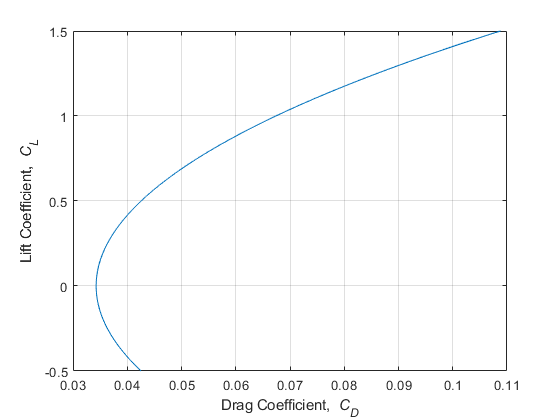


plot (CD,CL)
xlabel('Drag Coefficient, {\it C_{D}}')
ylabel('Lift Coefficient, {\it C_{L}}')
grid on


LDMax

LDMax = 14.8423